##  7.2 Chirp Scaling原理

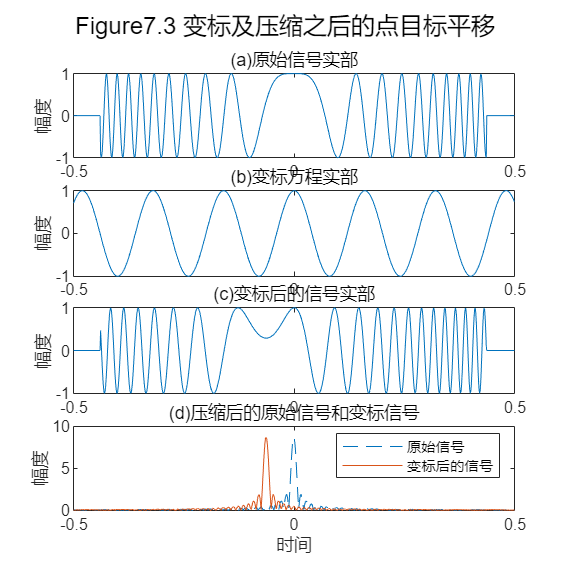

clc, clear, close all;
%% 参数设置
T = 1;
Fr = 800;
Nr = 700;
Kr = 100;
Bw = 87.5;
%% 参数计算
N = Fr*T;
Tr = Nr/Fr;
Delta_tau = 50/Fr;
%% 变量设置
t_0 = -Tr/2 : Tr/Nr : Tr/2-Tr/Nr;
t_p = -T/2 : T/N : T/2-T/N;
f = -Fr/2 : Fr/N : Fr/2-Fr/N;
%% 信号生成
s_0_t = zeros(1, N);
s_0_t(50:749) = exp(1j*pi*Kr*t_0.^2);
s_p_t = exp(1j*2*pi*Kr*t_p*Delta_tau);
%% 信号处理
s_1_t = s_0_t .* s_p_t;
%% 匹配滤波
H_f = exp(1j*pi*f.^2/Kr);
s_2_t = ifft(fftshift(fft(s_0_t, [], 2)) .* H_f, [], 2);
s_3_t = ifft(fftshift(fft(s_1_t, [], 2)) .* H_f, [], 2);
%% 绘制图形
H1 = figure();
set(H1,'position',[100,100,600,600]);  
subplot(411), plot(t_p, real(s_0_t)), ylabel('幅度'), title('(a)原始信号实部');
subplot(412), plot(t_p, real(s_p_t)), ylabel('幅度'), title('(b)变标方程实部');
subplot(413), plot(t_p, real(s_1_t)), ylabel('幅度'), title('(c)变标后的信号实部');
subplot(414), plot(t_p, abs(s_2_t), '--'), hold on, plot(t_p, abs(s_3_t)), hold off, legend('原始信号', '变标后的信号'), xlabel('时间'), ylabel('幅度'), title('(d)压缩后的原始信号和变标信号');
sgtitle('Figure7.3 变标及压缩之后的点目标平移');

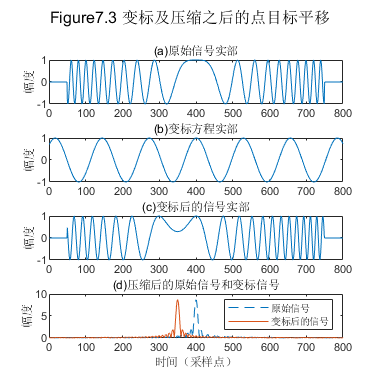

H2 = figure();
set(H2,'position',[100,100,600,600]);  
subplot(411), plot(real(s_0_t)), ylabel('幅度'), title('(a)原始信号实部');
subplot(412), plot(real(s_p_t)), ylabel('幅度'), title('(b)变标方程实部');
subplot(413), plot(real(s_1_t)), ylabel('幅度'), title('(c)变标后的信号实部');
subplot(414), plot(abs(s_2_t), '--'), hold on, plot(abs(s_3_t)), hold off, legend('原始信号', '变标后的信号'), xlabel('时间（采样点）'), ylabel('幅度'), title('(d)压缩后的原始信号和变标信号');
sgtitle('Figure7.3 变标及压缩之后的点目标平移');

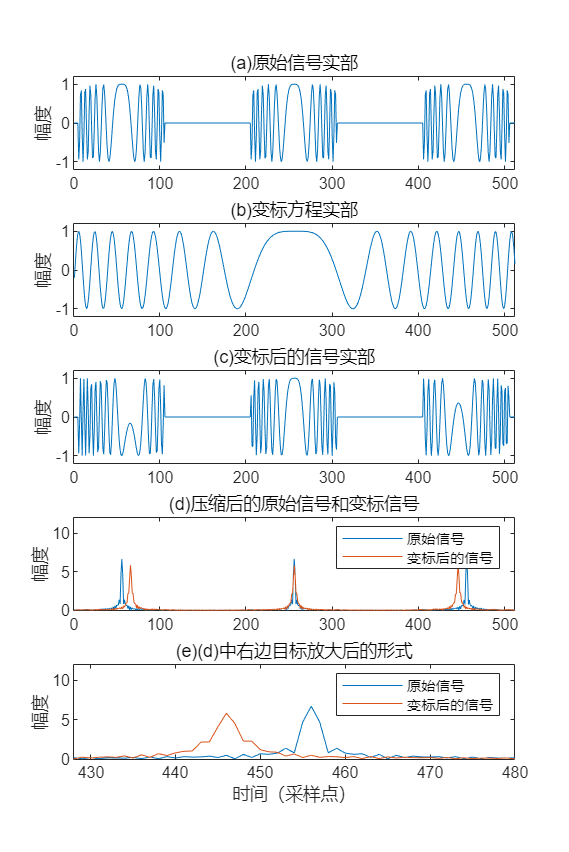

clc, clear, close all;
%% 参数设置 
N = 512;
Fr = 150;
Nr = 100;
Kr = 100;
%% 参数计算
T = N/Fr;
Tr = Nr/Fr;
alpha = 0.05;
%% 变量设置
t_0 = -T/2 : T/N : T/2-T/N;
t_1 = -Tr/2 : Tr/Nr : Tr/2-Tr/Nr;
f = -Fr/2 : Fr/N : Fr/2-Fr/N;
%% 信号生成
s_0_t = zeros(1, N);
s_0_t(6:105) = exp(1j*pi*Kr*t_1.^2);
s_0_t(206:305) = exp(1j*pi*Kr*t_1.^2);
s_0_t(406:505) = exp(1j*pi*Kr*t_1.^2);
s_p_t = exp(1j*pi*alpha*Kr*t_0.^2);
%% 信号处理
s_1_t = s_0_t .* s_p_t;
%% 匹配滤波
H_f = exp(1j*pi*f.^2/Kr);
s_2_t = ifft(fftshift(fft(s_0_t, [], 2)) .* H_f, [], 2);
s_3_t = ifft(fftshift(fft(s_1_t, [], 2)) .* H_f, [], 2);
%% 绘制图形
H3 = figure();
set(H3,'position',[100,100,600,900]); 
subplot(511), plot(real(s_0_t)), axis([0 512, -1.2 1.2]), ylabel('幅度'), title('(a)原始信号实部');
subplot(512), plot(real(s_p_t)), axis([0 512, -1.2 1.2]), ylabel('幅度'), title('(b)变标方程实部');
subplot(513), plot(real(s_1_t)), axis([0 512, -1.2 1.2]), ylabel('幅度'), title('(c)变标后的信号实部');
subplot(514), plot(abs(s_2_t)), hold on, plot(abs(s_3_t)), hold off, axis([0 512, 0 12]), legend('原始信号', '变标后的信号'), ylabel('幅度'), title('(d)压缩后的原始信号和变标信号');
subplot(515), plot(abs(s_2_t)), hold on, plot(abs(s_3_t)), hold off, axis([428 480, 0 12]), legend('原始信号', '变标后的信号'), xlabel('时间（采样点）'), ylabel('幅度'), title('(e)(d)中右边目标放大后的形式');

## 距离徙动校正中的Chirp Scaling

与一般插值方法相比，变标操作可以更高效、更精确地实现距离向插值，因此非常适合距离徙动校正。但是，在使用Chirp Scaling

之前必须满足以下两个条件：

1、距离向数据必须具有Chirp编码特性；

2、Chirp Scaling平移必须足够小，以避免出现超出距离采样率的混叠扩展频谱；

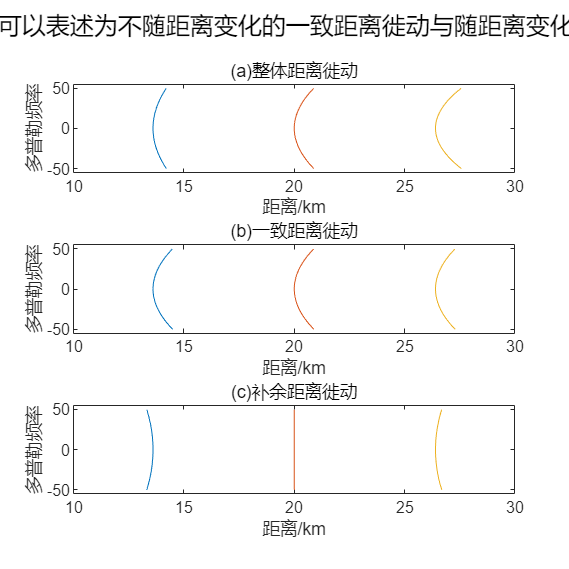

clc, clear, close all;
%% 参数设置
%  雷达参数
c = 3e8;
Vr = 150;
f0 = 5.3e9;
%  距离参数
R0 = 20e3;
Fr = 60e6;
Naz = 256;
%  方位参数
Fa = 100;
Nrg = 5120;
f_eta_c = 0;
%% 参数计算
%  雷达参数
lambda = freq2wavelen(f0);
%% 变量设置
R_mtx = [R0-Nrg/4/Fr*c; R0; R0+Nrg/4/Fr*c];
f_eta = -Fa/2 : Fa/Naz : Fa/2-Fa/Naz;
%% 信号生成
RCM_total = lambda^2/8/Vr^2*R_mtx.*(f_eta.^2 - f_eta_c^2);
RCM_bulk  = lambda^2/8/Vr^2*R0*ones(3,1).*(f_eta.^2 - f_eta_c^2);
RCM_diff  = lambda^2/8/Vr^2*(R_mtx - R0*ones(3,1)).*(f_eta.^2 - f_eta_c^2);
%% 绘制图形
H4 = figure();
set(H4,'position',[100,100,600,600]); 
subplot(311), plot(R_mtx(1,:)/1000 + RCM_total(1,:), f_eta, R_mtx(2,:)/1000 + RCM_total(2,:), f_eta, R_mtx(3,:)/1000 + RCM_total(3,:), f_eta), axis([10 30, -55 +55]), xlabel('距离/km'), ylabel('多普勒频率'), title('(a)整体距离徙动');
subplot(312), plot(R_mtx(1,:)/1000 + RCM_bulk(1,:), f_eta, R_mtx(2,:)/1000 + RCM_bulk(2,:), f_eta, R_mtx(3,:)/1000 + RCM_bulk(3,:), f_eta), axis([10 30, -55 +55]), xlabel('距离/km'), ylabel('多普勒频率'), title('(b)一致距离徙动');
subplot(313), plot(R_mtx(1,:)/1000 + RCM_diff(1,:), f_eta, R_mtx(2,:)/1000 + RCM_diff(2,:), f_eta, R_mtx(3,:)/1000 + RCM_diff(3,:), f_eta), axis([10 30, -55 +55]), xlabel('距离/km'), ylabel('多普勒频率'), title('(c)补余距离徙动');
sgtitle('Fig7.6 整体距离徙动可以表述为不随距离变化的一致距离徙动与随距离变化的补余距离徙动之和8');

%% 绘制图形